## Analyst script (iMicro)

**Import data and clean the outlier values of Hardness and Modulus (VALID ONLY FOR IMICRO TESTS)**

% Import data from spreadsheet
Test_number = input('Test number: ');
Test_sheet = cell(1, Test_number);
selected_file = "D:\Documentos\UNIVERSIDAD\TFG\Analyst\FS_B6_50mN.xlsx";
H_values = cell(1, 2);
M_values = cell(1, 2);
D_values = cell(1, 2);
maxNumRows = 0;

min_h_selected = 8;
max_h_selected = 10;
min_m_selected = 60;
max_m_selected = 80;

for i = 1:Test_number
    sheetName = "Test " + num2str(i); 
    Test_sheet{i} = readtable(selected_file, "Sheet", sheetName, "TextType", "string");

    % Outliers values cleaning (HARDNESS and MODULUS)
    Condition = (Test_sheet{i}.HARDNESS > min_h_selected & Test_sheet{i}.HARDNESS < max_h_selected) & ...
            (Test_sheet{i}.MODULUS > min_m_selected & Test_sheet{i}.MODULUS < max_m_selected);
    H_values{i} = Test_sheet{i}.HARDNESS(Condition);
    M_values{i} = Test_sheet{i}.MODULUS(Condition);
    D_values{i} = Test_sheet{i}.DEPTH(Condition);

    numRows = size(H_values{i}, 1);
    if numRows > maxNumRows
        maxNumRows = numRows;
    end
end

**Save cleaned data in an Excel file**



% Lee el archivo Excel
datos = readtable(selected_file);


% Crear la tabla final
df_final = table();

% Itera sobre las columnas DEPTH
for col = 1:width(datos)
    if strcmpi(datos.Properties.VariableNames{col}, 'DEPTH')
        % Extrae la columna DEPTH y agrega a la tabla final
        df_final.(sprintf('%s_DEPTH', datos.Properties.VariableNames{col})) = datos{:, col};
    end
end

% Guarda la tabla final en un nuevo archivo Excel
writetable(df_final, 'valores_depth.xlsx', 'Sheet', 'Sheet1');

% Lee el nuevo archivo Excel con los datos de DEPTH
valores_depth = readtable('valores_depth.xlsx', 'Sheet', 'Sheet1');

% Calcula el promedio y la desviación estándar por fila
promedio_filas_depth = mean(table2array(valores_depth(:, 2:end)), 2);
desviacion_filas_depth = std(table2array(valores_depth(:, 2:end)), 0, 2);




for i = 1:Test_number
    sheetName = "Test " + num2str(i); 
    Test_sheet{i} = readtable(selected_file, "Sheet", sheetName, "TextType", "string");

    % Outliers values cleaning (HARDNESS and MODULUS)
    Condition = (Test_sheet{i}.HARDNESS > min_h_selected & Test_sheet{i}.HARDNESS < max_h_selected) & ...
            (Test_sheet{i}.MODULUS > min_m_selected & Test_sheet{i}.MODULUS < max_m_selected);
    H_values{i} = Test_sheet{i}.HARDNESS(Condition);
    M_values{i} = Test_sheet{i}.MODULUS(Condition);
    D_values{i} = Test_sheet{i}.DEPTH(Condition);

    numRows = size(H_values{i}, 1);
    if numRows > maxNumRows
        maxNumRows = numRows;
    end
end

**Median and standard deviation calculus.**

Each rows of hardness/modulus values are appended to the H_average and H_std empty lists. Then, the average is obtained from the columns. First column corresponds to

the mean of the firts rows of every test, and so on.

H_values_per_row = zeros(maxNumRows, Test_number);
M_values_per_row = zeros(maxNumRows, Test_number);
D_values_per_row = zeros(maxNumRows, Test_number);

for i = 1:Test_number
    % Aplicar la condición antes de asignar valores a H_values_per_row
    Condition = (H_values{i} >= min_h_selected & H_values{i} <= max_h_selected);

    numRows = nnz(Condition); % Número de filas que cumplen la condición

    % Solo asignar valores que cumplen con la condición
    H_values_per_row(1:numRows, i) = H_values{i}(Condition);
    M_values_per_row(1:numRows, i) = M_values{i}(Condition);
    D_values_per_row(1:numRows, i) = D_values{i}(Condition);

    % Calcular las estadísticas solo para los valores que cumplen con la condición
    H_mean_per_row = mean(H_values_per_row(1:numRows, :), 2);
    H_std_per_row = std(H_values_per_row(1:numRows, :), 0, 2);
    M_mean_per_row = mean(M_values_per_row(1:numRows, :), 2);
    M_std_per_row = std(M_values_per_row(1:numRows, :), 0, 2);
    D_mean_per_row = mean(D_values_per_row(1:numRows, :), 2); 
    D_std_per_row = std(D_values_per_row(1:numRows, :), 0, 2);
    
end


**Graphic representation (INTERPOLATION METHOD)**

Interpolation of the values is applied to smooth the curves. Hardness and modulus in function of the penetration depth is represented.

D_sorted = sort(D_mean_per_row);
interpolation_levels = 100; % Select the number of values in DEPTH, equally separated

% INTERPOLATION
D_interp = linspace(max(D_sorted), min(D_sorted), interpolation_levels);
interp_H = interp1(D_sorted, H_mean_per_row, D_interp, "linear");
interp_M = interp1(D_sorted, M_mean_per_row, D_interp, "linear");

error_interp_H = interp1(D_sorted, H_std_per_row, D_interp, 'linear');
error_interp_M = interp1(D_sorted, M_std_per_row, D_interp, 'linear');

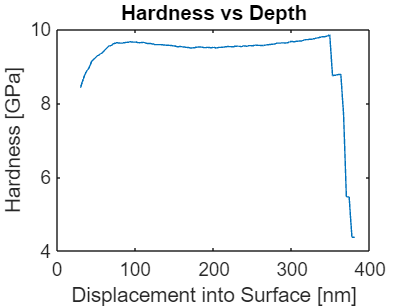

% Representation without error bars. Smoothing of the curves can be
% appreciated
plot(D_interp, interp_H)
title("Hardness vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Hardness [GPa]")

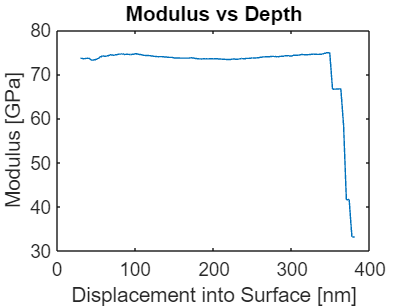


plot(D_interp, interp_M)
title("Modulus vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Modulus [GPa]")

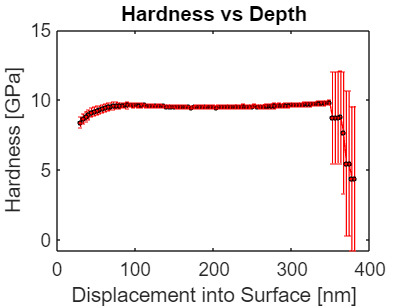

% Representation with error bars. 
error_bars = "vertical";
marker_face_color = "Red";
marker_edge_color = "Black";
line_color = "Red";
marker_size = 3;
capsize = 3;
linewidth =0.9;
errorbar(D_interp, interp_H, error_interp_H, "o-", error_bars,"Color",line_color, "MarkerFaceColor",marker_face_color, "MarkerEdgeColor",marker_edge_color,"MarkerSize",marker_size, ...
    "CapSize", capsize,"LineWidth",linewidth)
title("Hardness vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Hardness [GPa]")

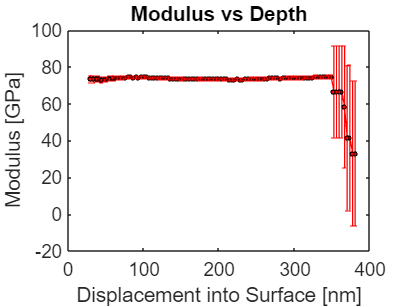


errorbar(D_interp, interp_M, error_interp_M, "o-", error_bars,"Color",line_color, "MarkerFaceColor",marker_face_color, "MarkerEdgeColor",marker_edge_color,"MarkerSize",marker_size, ...
    "CapSize", capsize,"LineWidth",linewidth)
title("Modulus vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Modulus [GPa]")

**Graphic representation ("NUMBER OF VALUES" method)**

The error bars are represented for each number of certain values (specified by the user). Following this method, the regions of the plot that have a larger amount of values can be spotted.

D_sorted = sort(D_mean_per_row);

Unrecognized function or variable 'D_mean_per_row'.


error_spacing = 50; % The error bar will be plotted each "error_spacing" values

% Crear un índice para seleccionar cada error_spacing valor de D_interp
error_indices = 1:error_spacing:length(D_sorted);

error_bars = "vertical";
marker_face_color = "Red";
marker_edge_color = "Red";
line_color = "Blue";
marker_size = 3;
capsize = 7;
linewidth =0.9;

% Graficar barras de error cada cierto número de valores
errorbar(D_sorted(error_indices), H_mean_per_row(error_indices), H_std_per_row(error_indices), "o-", error_bars,"Color",line_color, "MarkerFaceColor",marker_face_color, "MarkerEdgeColor",marker_edge_color,"MarkerSize",marker_size, ...
    "CapSize", capsize,"LineWidth",linewidth)
title("Hardness vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Hardness [GPa]")

% Repetir el proceso para Modulus vs Depth
errorbar(D_sorted(error_indices), M_mean_per_row(error_indices), M_std_per_row(error_indices), "o-", error_bars,"Color",line_color, "MarkerFaceColor",marker_face_color, "MarkerEdgeColor",marker_edge_color,"MarkerSize",marker_size, ...
    "CapSize", capsize,"LineWidth",linewidth)
title("Modulus vs Depth")
xlabel("Displacement into Surface [nm]")
ylabel("Modulus [GPa]")